clc;
clear all;
l1=30; %Length of Link 1
l2=30; %Length of Link 2
l3=10;  %Length of Link 3
l4 =10; %Length of Link 4
% DHparameter=[0 pi/2 0.04 0;
%              0.12 0 0 13*pi/30+pi/2;
%              0.194 -pi/2 0 -23*pi/30+pi/2;
%              0 0 0.176 0;
%              0 pi/2 0 pi/2;
%              0 0 0 0]
DHparameter=[0 pi/2 40 0;
             120 0 0 13*pi/30+pi/2;
             194 -pi/2 0 -23*pi/30+pi/2;
             0 0 176 0;
             0 pi/2 0 pi/2;
             0 0 0 0]

DHparameter =          0    1.5708   40.0000         0
  120.0000         0         0    2.9322
  194.0000   -1.5708         0   -0.8378
         0         0  176.0000         0
         0    1.5708         0    1.5708
         0         0         0         0


## `Defining the asymmetric robot as a rigid tree`

%Defining a Robot Rigid Body Tree 
dental = rigidBodyTree("MaxNumBodies",6,"DataFormat","column");

%Setting the Gravity matrix w.r.t to the base frame of robot.
dental.Gravity = [0 0 -9.81];

%Creating links and joints
body1 = rigidBody('Body1');
joint1 = rigidBodyJoint('Joint1','revolute');
% joint1.PositionLimits = [-pi/3 pi/3];
body1.Mass = 10;
body1.CenterOfMass = [0 0 0];
body2 = rigidBody('Body2');
joint2 = rigidBodyJoint('Joint2','revolute');
joint2.HomePosition = 13*pi/30+pi/2;
body2.Mass = 10;
body2.CenterOfMass = [0 0 0];
body3 = rigidBody('Body3');
joint3 = rigidBodyJoint('Joint3','revolute');
body3.Mass = 10;
joint3.HomePosition = -23*pi/30+pi/2;
% joint3.PositionLimits = [-10 10]; %Position limit defines the maximum extension/retraction from mean position for a prismatic joint. 
body3.CenterOfMass = [0 0 0];
body4 = rigidBody('Body4');
joint4 = rigidBodyJoint('Joint4','revolute');
body4.Mass = 10;

body5 = rigidBody('Body5');
joint5 = rigidBodyJoint('Joint5','revolute');
% joint5.HomePosition = pi/2;
% joint5.PositionLimits = [0 0.1];
body5.Mass = 10;

body6 = rigidBody('Body6');
joint6 = rigidBodyJoint('Joint6','revolute');
% joint6.PositionLimits = [0 0.1];
body6.Mass = 10;

%Settings the transformations to each joint with DH parameter.
%Assigning the joint of each link with the object 
setFixedTransform(joint1,DHparameter(1,:),"dh");
body1.Joint = joint1;
setFixedTransform(joint2,DHparameter(2,:),"dh");
body2.Joint = joint2;
setFixedTransform(joint3,DHparameter(3,:),"dh");
body3.Joint = joint3;
setFixedTransform(joint4,DHparameter(4,:),"dh");
body4.Joint = joint4;
setFixedTransform(joint5,DHparameter(5,:),"dh");
body5.Joint = joint5;
setFixedTransform(joint6,DHparameter(6,:),"dh");
body6.Joint = joint6;

addBody(dental,body1,'base');
addBody(dental,body2,'Body1');
addBody(dental,body3,'Body2');
addBody(dental,body4,'Body3');
addBody(dental,body5,'Body4');
addBody(dental,body6,'Body5');

showdetails(dental)

--------------------
Robot: (6 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        Body1        Joint1      revolute             base(0)   Body2(2)  
   2        Body2        Joint2      revolute            Body1(1)   Body3(3)  
   3        Body3        Joint3      revolute            Body2(2)   Body4(4)  
   4        Body4        Joint4      revolute            Body3(3)   Body5(5)  
   5        Body5        Joint5      revolute            Body4(4)   Body6(6)  
   6        Body6        Joint6      revolute            Body5(5)   
--------------------


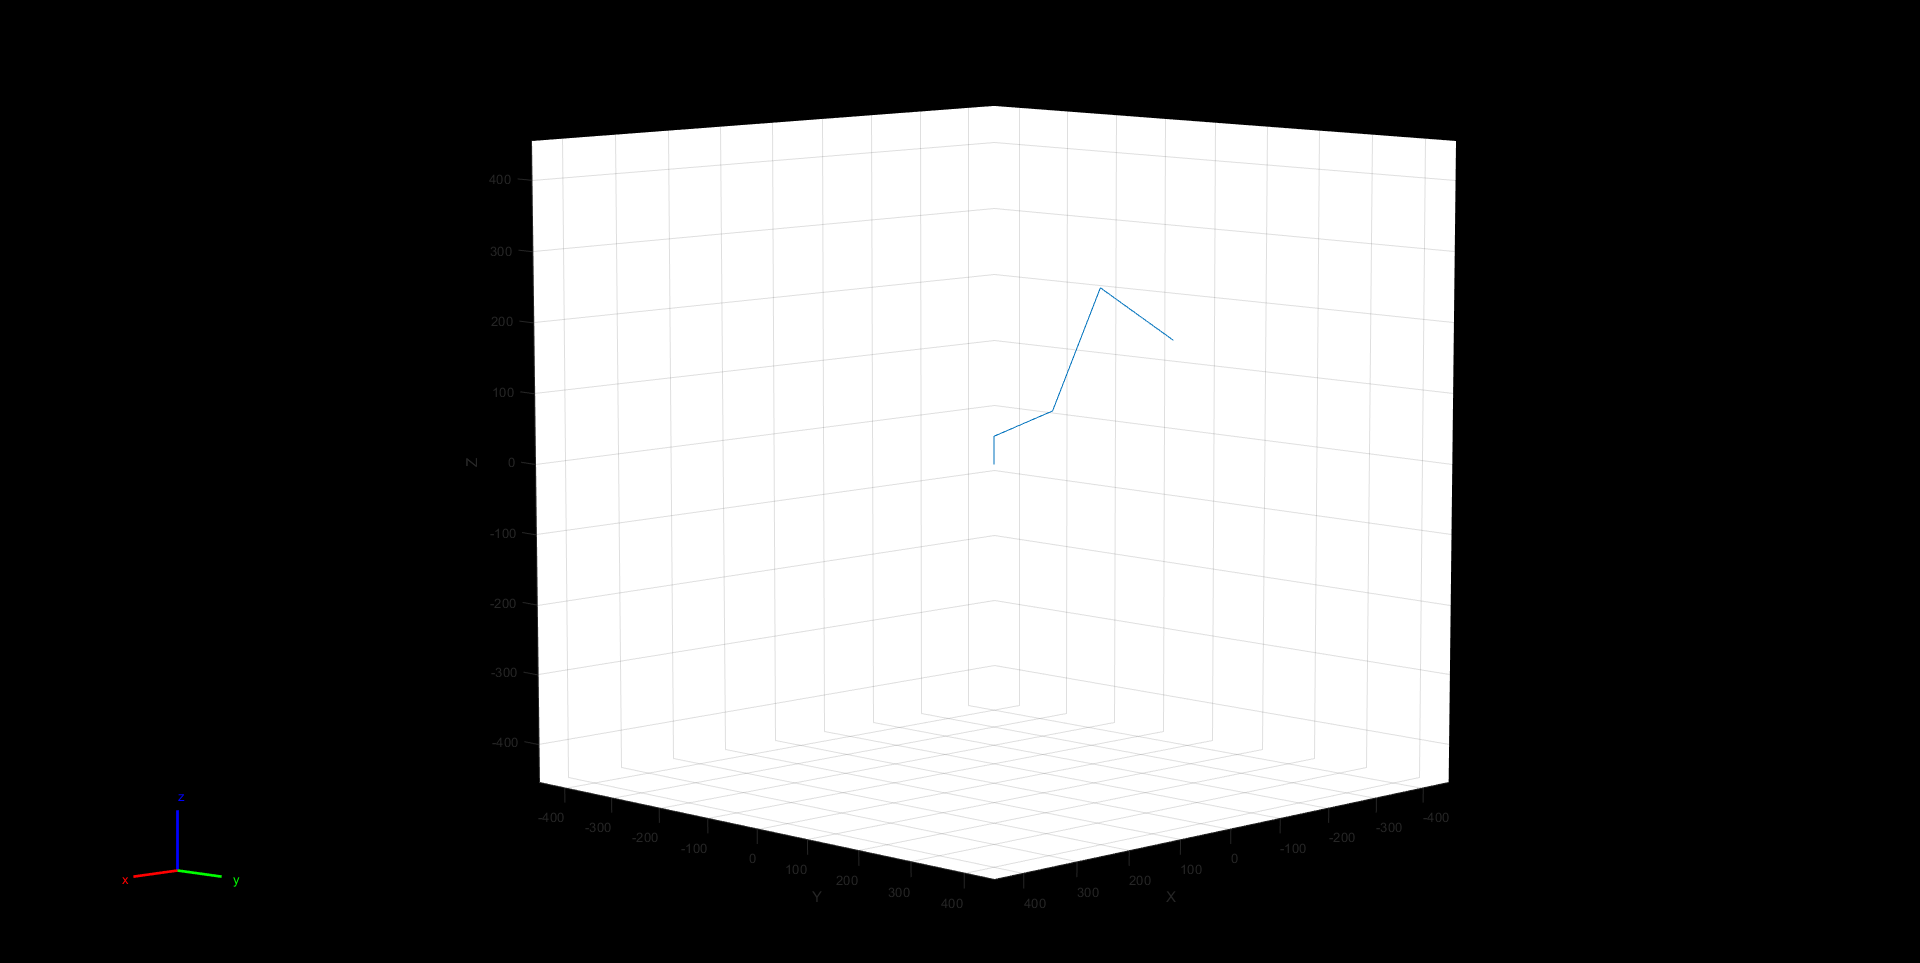


show(dental);

## `Denture, 3 - Teeth, 1 - Tooth, Final Tooth, Transformation and Shrink`

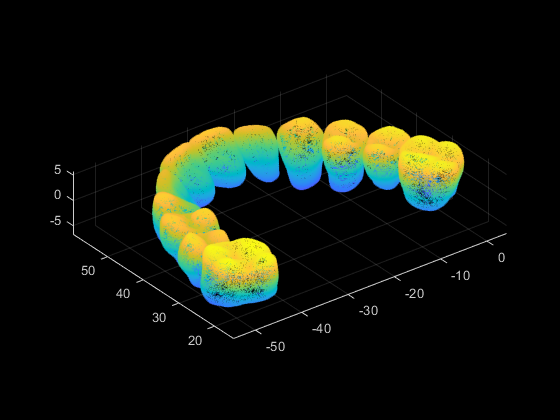

% Read and plot complete denture
stlData = stlread('1-3dm.stl');
points = stlData.Points;
ptCloud = pointCloud(points);
figure
pcshow(ptCloud)

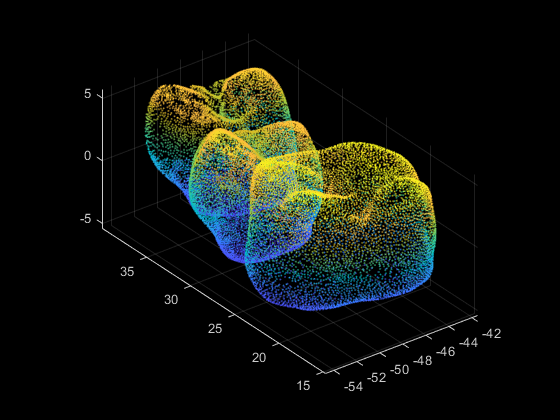


% Select and plot three teeth individually
roi = [-60 -40 10 40 -6 6]; % region of interest
indices = findPointsInROI(ptCloud,roi);
ptCloudB = select(ptCloud, indices);
pcshow(ptCloudB.Location);

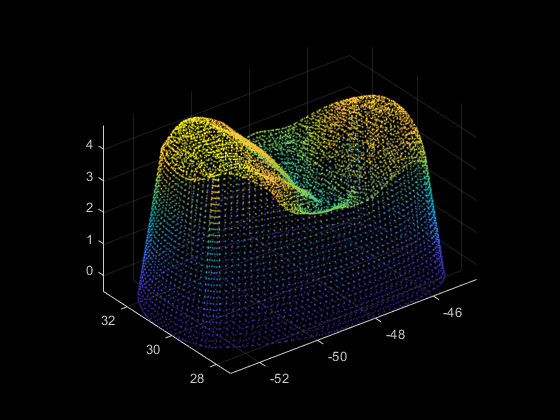


% Import and plot final model individually
stlData_fin = stlread("1tooth_mesh2.STL");

points_fin= stlData_fin.Points;
ptCloud_fin = pointCloud(points_fin);
pcshow(ptCloud_fin);

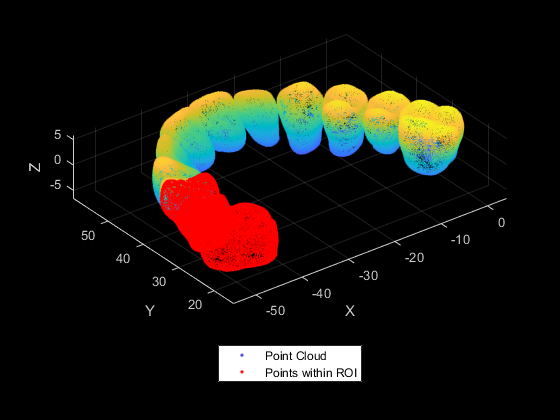


% Three teeth in the denture
figure
pcshow(ptCloud);
hold on;
pcshow(ptCloudB.Location,'r');
legend('Point Cloud','Points within ROI','Location','southoutside','Color',[1 1 1])
xlabel('X'); ylabel('Y'); zlabel('Z');
hold off;

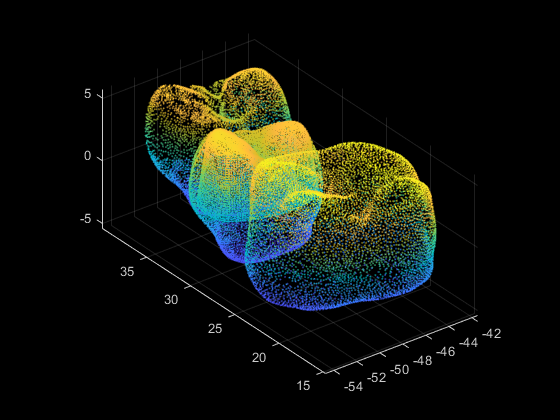


% Final tooth inside the considered tooth
figure
pcshow(ptCloudB.Location);
hold on;
pcshow(ptCloud_fin);
hold off;

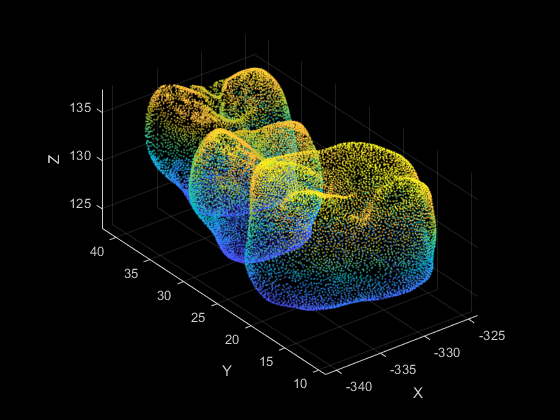


%Transformation (shrink and move)
Sx = 1.3;
Sy = 1.3;
Sz = 1.3;


tform = affine3d([Sx 0 0 0; 0 Sy 0 0; 0 0 Sz 0; 0 0 0 1]);
ptCloud_3t = pctransform(ptCloudB,tform);
ptCloud_fin = pctransform(ptCloud_fin,tform);
rot = [1 0 0; 0 1 0; 0 0 1];
zCoord = 130;
trans = 1000*[-0.27 -0.01 zCoord/1000];
rigid_tform = rigid3d(rot,trans);
ptCloud_3t = pctransform(ptCloud_3t,rigid_tform);
ptCloud_fin = pctransform(ptCloud_fin,rigid_tform);

figure
pcshow(ptCloud_3t)
xlabel('X'); ylabel('Y'); zlabel('Z')

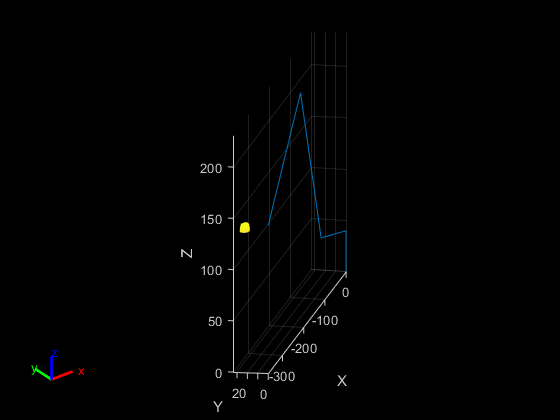

pcshow(ptCloud_fin)
xlabel('X'); ylabel('Y'); zlabel('Z')
hold on
show(dental);

## `STL files for neighboring teeth`

stlData = stlread('Single_Back_tooth.stl');
points = stlData.Points;
backTooth = pointCloud(points);

stlData = stlread('Single_front_tooth.stl');
points = stlData.Points;
frontTooth = pointCloud(points);

% frontTooth = pctransform(frontTooth,tform);
% frontTooth = pctransform(frontTooth,rigid_tform);

%Merge
neighboringTeeth = pcmerge(frontTooth, backTooth, 1);

%Transformation (shrink and move)
neighboringTeeth = pctransform(neighboringTeeth,tform);
neighboringTeeth = pctransform(neighboringTeeth,rigid_tform);


% pcshow(neighboringTeeth)
% xlabel('X'); ylabel('Y'); zlabel('Z')

## `Curves for end-effector path planning`

Algo

- set Z range

- get Z -> getContour

- get ordered points -> getOrderedPoints()

- smoothen curve -> smoothCurve()

- Make polyshape

- Expand polyshape

figure
allPoints = {};
r = 0.5

r = 0.5000

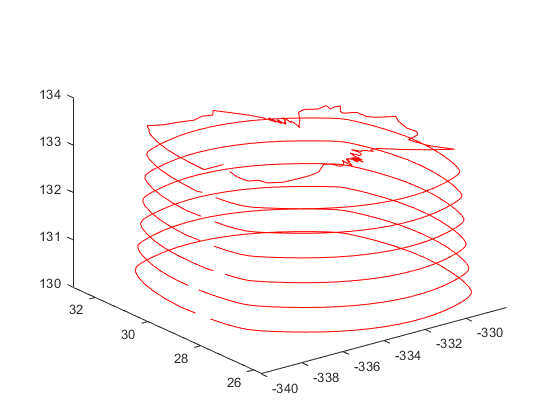

for i=1:7
    L = zCoord + (i-1)*r;
    H = zCoord + r + (i-1)*r;
    [a,b] = getContour(ptCloud_fin,L,H);
    P = getOrderedPoints(a,b);
    [smoothX,smoothY] = smoothCurve(P,35,2);
    
    points = downsample([smoothX',smoothY'],5);
   
    polyin = polyshape({points(:,1)},{points(:,2)});
    polyout = polybuffer(polyin,0.01);
    
    zin = (L+H)/2 * ones(length(polyin.Vertices),1);
    allPoints{i} = [points,zin];
%     zout = (L+H)/2 * ones(length(polyout.Vertices));
    
    plot3(polyin.Vertices(:,1),polyin.Vertices(:,2),zin,"Color",[1 0 0]); hold on;
%     plot3(polyout.Vertices(:,1),polyout.Vertices(:,2),zout,"Color",[0 1 0]);
end

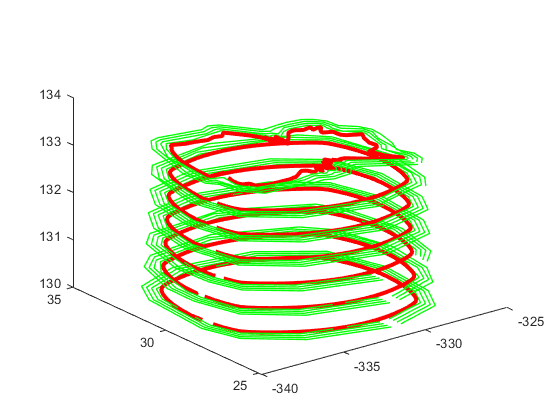

figure
for i=1:length(allPoints)
    polyin = polyshape({allPoints{1,i}(:,1)},{allPoints{1,i}(:,2)});
    plot3(polyin.Vertices(:,1),polyin.Vertices(:,2),allPoints{1,i}(:,3),...
            "Color",[1 0 0],"LineWidth",3);
    hold on;
    for j=1:4
        polyout = polybuffer(polyin,0.2*j);
        polyout.Vertices = downsample(polyout.Vertices,20);
        z = allPoints{1,i}(1,3)*ones(length(polyout.Vertices),1);
        allPoints{j+1,i} = [polyout.Vertices, z];
        plot3(polyout.Vertices(:,1),polyout.Vertices(:,2),z,...
                "Color",[0 1 0],"LineWidth",1);
    end
end

allPoints

allPoints = 5×7 cell array
    {57×3 double}    {76×3 double}    {68×3 double}    {57×3 double}    {57×3 double}    {58×3 double}    {145×3 double}
    {13×3 double}    {14×3 double}    {13×3 double}    {13×3 double}    {13×3 double}    {14×3 double}    { 60×3 double}
    {13×3 double}    {14×3 double}    {13×3 double}    {13×3 double}    {13×3 double}    {14×3 double}    { 46×3 double}
    {13×3 double}    {14×3 double}    {13×3 double}    {13×3 double}    {13×3 double}    {14×3 double}    { 40×3 double}
    {13×3 double}    {14×3 double}    {13×3 double}    {13×3 double}    {13×3 double}    {13×3 double}    { 35×3 double}


% Row = Top to Bottom - Inside to Outside
% Column = Left to Right - Bottom to Top

## `Save all quarters in arrays`

curve1 = allPoints{5,1}

curve1 =  -332.0745   24.8728  130.2500
 -336.3735   25.6280  130.2500
 -338.8378   27.0348  130.2500
 -339.4825   28.5365  130.2500
 -339.1189   31.6867  130.2500
 -338.2737   32.8323  130.2500
 -335.5208   33.5931  130.2500
 -331.1364   33.1596  130.2500
 -328.2288   31.7023  130.2500
 -327.2593   29.4631  130.2500


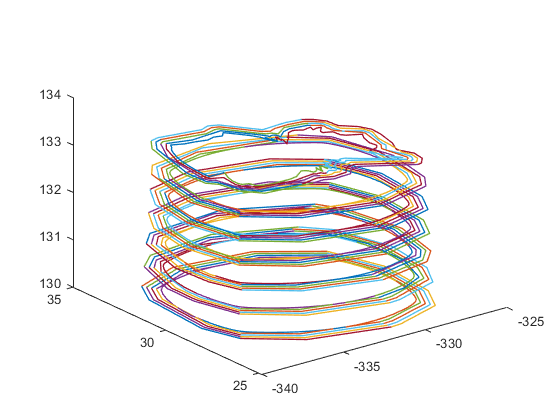

appendAllPoints = [];
figure

for i=1:7
    for j = 1:2 %Offsetting inner most contour fix
        [q1,q2,q3,q4] = getQuarters(allPoints{j,i},1);
        q1_arr{i,j} = q2;
        q2_arr{i,j} = q1;
        q3_arr{i,j} = q4;
        q4_arr{i,j} = q3;
        appendAllPoints = [appendAllPoints;q1;q2;q3;q4];
    end
    for j=2:5
        [q1,q2,q3,q4] = getQuarters(allPoints{j,i},1);
        q1_arr{i,j} = q1;
        q2_arr{i,j} = q2;
        q3_arr{i,j} = q3;
        q4_arr{i,j} = q4;
        appendAllPoints = [appendAllPoints;q1;q2;q3;q4];
    end
end

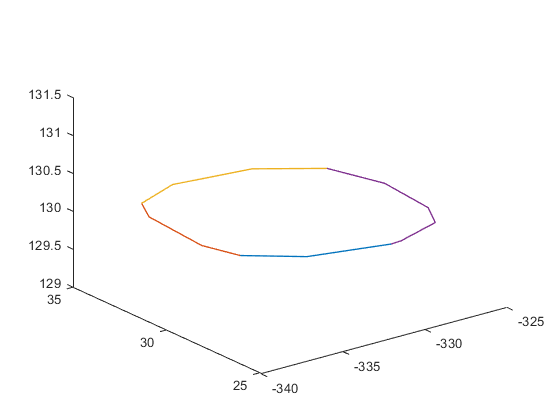

% Show a single curve.
figure
[q1,q2,q3,q4] = getQuarters(allPoints{5,1},1);


% q2 is front
% q1 is right
% q3 is left
% q4 is back

## `Splitting Geometry and Forming into Trajectory`

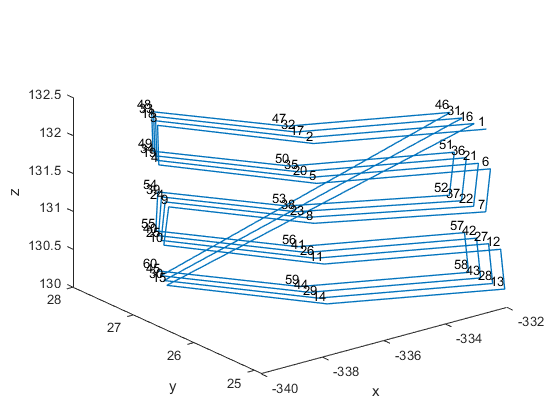

%Plot a single quarter
% figure
% for i=1:5
%     for j=1:5
%         plot3(q1_arr{i,j}(:,1),q1_arr{i,j}(:,2),q1_arr{i,j}(:,3),"LineWidth",1);hold on;
%     end
% end

q1_traj_arr = orderQuarter(q1_arr);
q2_traj_arr = orderQuarter(q2_arr);
q3_traj_arr = orderQuarter(q3_arr);
q4_traj_arr = orderQuarter(q4_arr);

q1_traj_arr_fixed = [];
for i = 1:60
    q1_traj_arr_fixed(i,:) = q1_traj_arr(i,:);
end

q2_traj_arr_fixed = [];
for i = 1:80
    q2_traj_arr_fixed(i,:) = q2_traj_arr(i,:);
end

q3_traj_arr_fixed = [];
for i = 1:80
    q3_traj_arr_fixed(i,:) = q3_traj_arr(i,:);
end

q4_traj_arr_fixed = [];
for i = 1:135
    q4_traj_arr_fixed(i,:) = q4_traj_arr(i,:);
end

save fixed_contour.mat q1_traj_arr_fixed q2_traj_arr_fixed q3_traj_arr_fixed q4_traj_arr_fixed

figure
plotQuarter(q1_traj_arr_fixed);
xlabel('x'); ylabel('y'); zlabel('z');

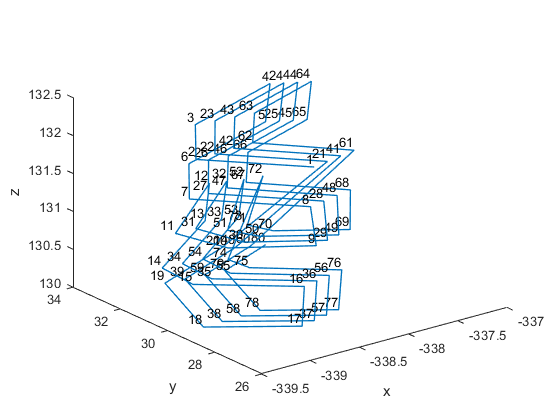

plotQuarter(q2_traj_arr_fixed);
xlabel('x'); ylabel('y'); zlabel('z');

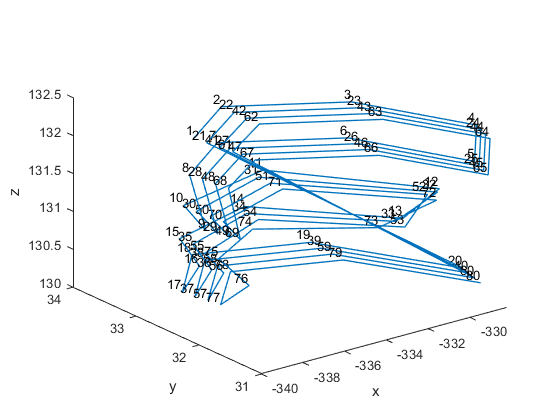

plotQuarter(q3_traj_arr_fixed);
xlabel('x'); ylabel('y'); zlabel('z');

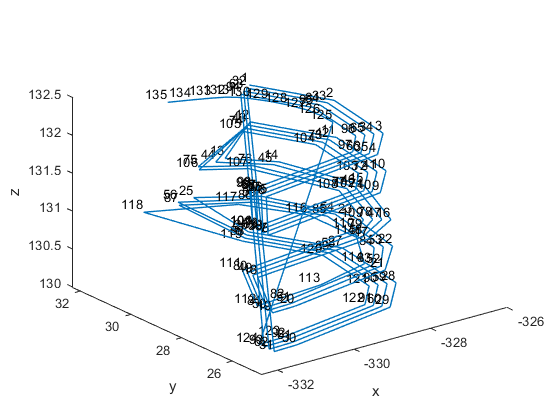

plotQuarter(q4_traj_arr_fixed);
xlabel('x'); ylabel('y'); zlabel('z');
hold off

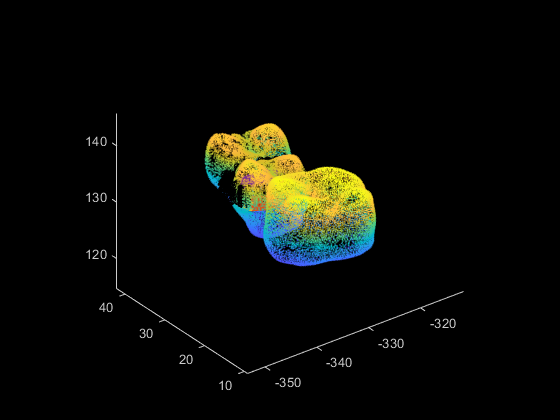


figure
hold on
pcshow(ptCloud_3t)
plotQuarter(q1_traj_arr_fixed);
plotQuarter(q2_traj_arr_fixed);
plotQuarter(q3_traj_arr_fixed);
plotQuarter(q4_traj_arr_fixed);

## `Calculate IK for Trajectories`

ik = inverseKinematics("RigidBodyTree",dental);
weights = [0 0 0 1 1 1];
q0 = homeConfiguration(dental);
qinitial = q0;
% ik.SolverParameters.MaxIterations = 45000;
% ik.SolverParameters.MaxTime = 1000
for i = 1:length(q1_traj_arr_fixed)
%     point = q1_traj_arr(i,:);
    pose = trvec2tform(q1_traj_arr_fixed(i,:));
    [qsol, solinfo] = ik("Body6",pose,weights,qinitial);
    q1_config(:,i) = qsol;
    qinitial=qsol;
    solinfo
end

solinfo = struct with fields:
           Iterations: 42
    NumRandomRestarts: 1
        PoseErrorNorm: 2.6750e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2800e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 7.8416e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0266e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0437e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 5.8551e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 9.9140e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 6.3775e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2502e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6144e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 3.5533e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 3.9289e-12
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 5.8118e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 5.4139e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7408e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2913e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 8.0194e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 3.5500e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 2.9482e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5761e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 4.8676e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0514e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 1.8501e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5786e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5893e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5402e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 9.7995e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 5.2618e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 4.4848e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 4.2118e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0112e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 5.6755e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3916e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 3.1277e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5295e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 9.6315e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 4.8891e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9286e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 4.5942e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.4010e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7049e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9018e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 4.4746e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 3.3691e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4497e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 7.0837e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9159e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 4.3240e-12
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 3.3457e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 7.7092e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2463e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2577e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 2.3789e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 5.4543e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 8.7010e-12
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2788e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1956e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 3.3781e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 2.7453e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 7.1891e-10
             ExitFlag: 1
               Status: 'success'


% q1_traj_arr(5,:)
% getTransform(dental,q1_config(:,5),'Body6')

qinitial = q0;
for i = 1:length(q2_traj_arr_fixed)
    pose = trvec2tform(q2_traj_arr_fixed(i,:));
    [qsol, solinfo] = ik("Body6",pose,weights,qinitial);
    q2_config(:,i) = qsol;
    qinitial=qsol;
    solinfo
end

solinfo = struct with fields:
           Iterations: 65
    NumRandomRestarts: 2
        PoseErrorNorm: 1.3688e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7281e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2836e-12
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 5.4712e-13
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7190e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 8.9005e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5234e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 2.3139e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 7.3522e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4400e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 2.8054e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 5.8993e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 5.6010e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 3.5527e-15
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 4.7076e-12
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 4.7931e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 7.9588e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 1.8020e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 3.0642e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9150e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5205e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0573e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9717e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 2.9468e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 4.5291e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 8.0270e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 3.3637e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2337e-13
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0498e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 4.2042e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 8.0749e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 7.4779e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 8.4635e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2203e-12
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 2.7275e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 2.8910e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 4.7635e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3942e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3491e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 3.1052e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 26
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4257e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 4.1724e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 6.7150e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 5.9957e-12
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 3.7438e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.1559e-12
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 5.6711e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 9.6439e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 1.8249e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 6.0779e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 5.9305e-12
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 2.7784e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5553e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 4.5145e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 6.2552e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0448e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 2.1272e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0695e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 3.2220e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 6.1609e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 6.2744e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6197e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 4.3549e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5990e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 5.4388e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 7.7820e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 3.0058e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5579e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2119e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 2.9356e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2409e-12
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 4.2739e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 2.8575e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 4.2924e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4333e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 3.1305e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9487e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 4.5005e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 4.9007e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.6884e-10
             ExitFlag: 1
               Status: 'success'


qinitial = q0;
for i = 1:length(q3_traj_arr_fixed)
    pose = trvec2tform(q3_traj_arr_fixed(i,:));
    [qsol, solinfo] = ik("Body6",pose,weights,qinitial);
    q3_config(:,i) = qsol;
    qinitial=qsol;
    solinfo
end

solinfo = struct with fields:
           Iterations: 61
    NumRandomRestarts: 2
        PoseErrorNorm: 7.4197e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 8.5150e-12
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 8.8706e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 2.4801e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 6.3146e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 5.3906e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 3.0733e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 7.9028e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5336e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 5.8664e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 2.3766e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 6.9430e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 5.8685e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 2.1364e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7294e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6712e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 2.6287e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5440e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1276e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 1.8283e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6948e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2539e-12
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 4.6166e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 3.3414e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 7.6664e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9405e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6631e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0020e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 4.4004e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 26
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4538e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2555e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 8.1203e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 3.0491e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 2.1561e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 8.2229e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1294e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 7.1524e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 5.3893e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 4.0799e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 2.4749e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 5.3139e-13
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 7.0788e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 8.1361e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 9.2037e-12
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1013e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 3.2802e-12
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6762e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 26
    NumRandomRestarts: 0
        PoseErrorNorm: 9.5353e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 9.7090e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 5.1962e-13
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 6.4555e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5507e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2564e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5005e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2621e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 8.9107e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 4.1565e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 3.6691e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 7.8861e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 3.7835e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 7.0252e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 3.3117e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 3.3471e-12
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 2.3260e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 4.2233e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7418e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2503e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 7.9647e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0681e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 3.3412e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 6.4630e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1893e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 2.7472e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 7.5776e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 2.4333e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 4.2012e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 7.4288e-12
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4005e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 3.1390e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0734e-10
             ExitFlag: 1
               Status: 'success'


qinitial = q0;
for i = 1:length(q4_traj_arr_fixed)
    pose = trvec2tform(q4_traj_arr_fixed(i,:));
    [qsol, solinfo] = ik("Body6",pose,weights,qinitial);
    q4_config(:,i) = qsol;
    qinitial=qsol;
    solinfo
end

solinfo = struct with fields:
           Iterations: 66
    NumRandomRestarts: 2
        PoseErrorNorm: 2.9304e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2098e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 4.6788e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7621e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7972e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 7.1438e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0718e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 6.6088e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4329e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2264e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 9.0717e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 7.2990e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9513e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 7.1720e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 4.3545e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7090e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4740e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9353e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5284e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7777e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 26
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7848e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 5.7776e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 5.7281e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 3.1447e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 5.9315e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 4.9467e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 2.6674e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 7.6639e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 3.7884e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 6.6352e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5565e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 9.6021e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 6.5586e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 6.0150e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0841e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 5.6920e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0033e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 2.8461e-12
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3737e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 6.3913e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 3.5235e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 9.4584e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 4.9474e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9011e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 2.4443e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 3.1781e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 3.8226e-12
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 6.7908e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 4.3078e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6757e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1010e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0021e-12
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2834e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 4.7891e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 26
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5170e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 6.0798e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 3.5216e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 9.4973e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5795e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7186e-13
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.9610e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0555e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 4.8892e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.9109e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 8.4520e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 3.2711e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0814e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 3.0713e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1069e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5142e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 4.5073e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 4.4656e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4854e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 8.2820e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 4.9249e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0228e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 7.9676e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 3.2879e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1820e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 3.2353e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0584e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 4.0636e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 3.6647e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 3.1229e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 5.4721e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 8.5762e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 3.3380e-12
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0183e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 7.9190e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 26
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9196e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 2.3801e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 1.8302e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5922e-12
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 3.2077e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 7.8881e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 8.6488e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 2.9298e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0226e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 7.2314e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3141e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5622e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 9.4317e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 6.6021e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 4.8693e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4748e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6088e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5753e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 2.7728e-12
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1545e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0683e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 6.6165e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 8.5665e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 4.6093e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0246e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 6.4280e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 3.4131e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 7.9020e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2756e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 1.8394e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 8.6540e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 2.6881e-12
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 6.4652e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4248e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0716e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 4.6171e-12
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 9.8245e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 3.2537e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 6.0337e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2473e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 4.2297e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 2.1500e-12
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 2.3860e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 4.9944e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3464e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 3.0439e-11
             ExitFlag: 1
               Status: 'success'


save q_configs q1_config q2_config q3_config q4_config;
% q_config = matfile('q_configs.mat');
% q1_config = q_config.q1_config;
% q1_config = trapveltraj(q1_config,length(q1_config(1,:)),"EndTime",2);


%Combine and add home config between
homeConfig = findHomeConfig(ptCloud_fin);
pose = trvec2tform(homeConfig);
home = ik("Body6",pose,weights,dental.homeConfiguration);
%Need to get traj between last config of each q and home, then add these
%trajs to q_tot
t = 20;
q_1tohome = trapveltraj([q1_config(:,length(q1_config(1,:))),home],t,"EndTime",2);
q_hometo2 = trapveltraj([home,q2_config(:,1)],t,"EndTime",2);
q_2tohome = trapveltraj([q2_config(:,length(q2_config(1,:))),home],t,"EndTime",2)

q_2tohome =    -0.0954   -0.0953   -0.0952   -0.0950   -0.0946   -0.0942   -0.0936   -0.0930   -0.0924   -0.0918   -0.0911   -0.0905   -0.0899   -0.0893   -0.0888   -0.0883   -0.0880   -0.0877   -0.0876   -0.0875
   -2.7931   -2.7600   -2.6608   -2.4954   -2.2638   -1.9661   -1.6022   -1.1868   -0.7678   -0.3488    0.0703    0.4893    0.9083    1.3237    1.6876    1.9853    2.2168    2.3823    2.4815    2.5146
   -1.6100   -1.5980   -1.5618   -1.5015   -1.4170   -1.3084   -1.1757   -1.0243   -0.8715   -0.7187   -0.5659   -0.4131   -0.2603   -0.1088    0.0239    0.1325    0.2169    0.2772    0.3134    0.3255
   -0.5735   -0.5700   -0.5592   -0.5414   -0.5163   -0.4842   -0.4448   -0.4000   -0.3547   -0.3094   -0.2641   -0.2188   -0.1736   -0.1287   -0.0894   -0.0572   -0.0322   -0.0143   -0.0036         0
    0.5962    0.5925    0.5814    0.5628    0.5368    0.5033    0.4625    0.4158    0.3687    0.3217    0.2746    0.2275    0.1804    0.1338    0.0929    0.0595    0.0334    0.0149    

q_hometo3 = trapveltraj([home,q3_config(:,1)],t,"EndTime",2);
q_3tohome = trapveltraj([q3_config(:,length(q3_config(1,:))),home],t,"EndTime",2);
q_hometo4 = trapveltraj([home,q4_config(:,1)],t,"EndTime",2);


% q_tot = [q1_config ];
q_tot = [q1_config q2_config q3_config q4_config];

## `Finding the collision free trajectory`

% Need a mesh of the tooth
MSH = collisionMesh(ptCloud_fin.Location);
worldCollisionArray = {MSH};
robotCollision = isInCollision(q_tot, MSH, dental);
if ~robotCollision
    disp("The robot is not in collision.")
else
    disp("The robot is in collision")
end

The robot is not in collision.


## `Calculate and Plot Closest points`

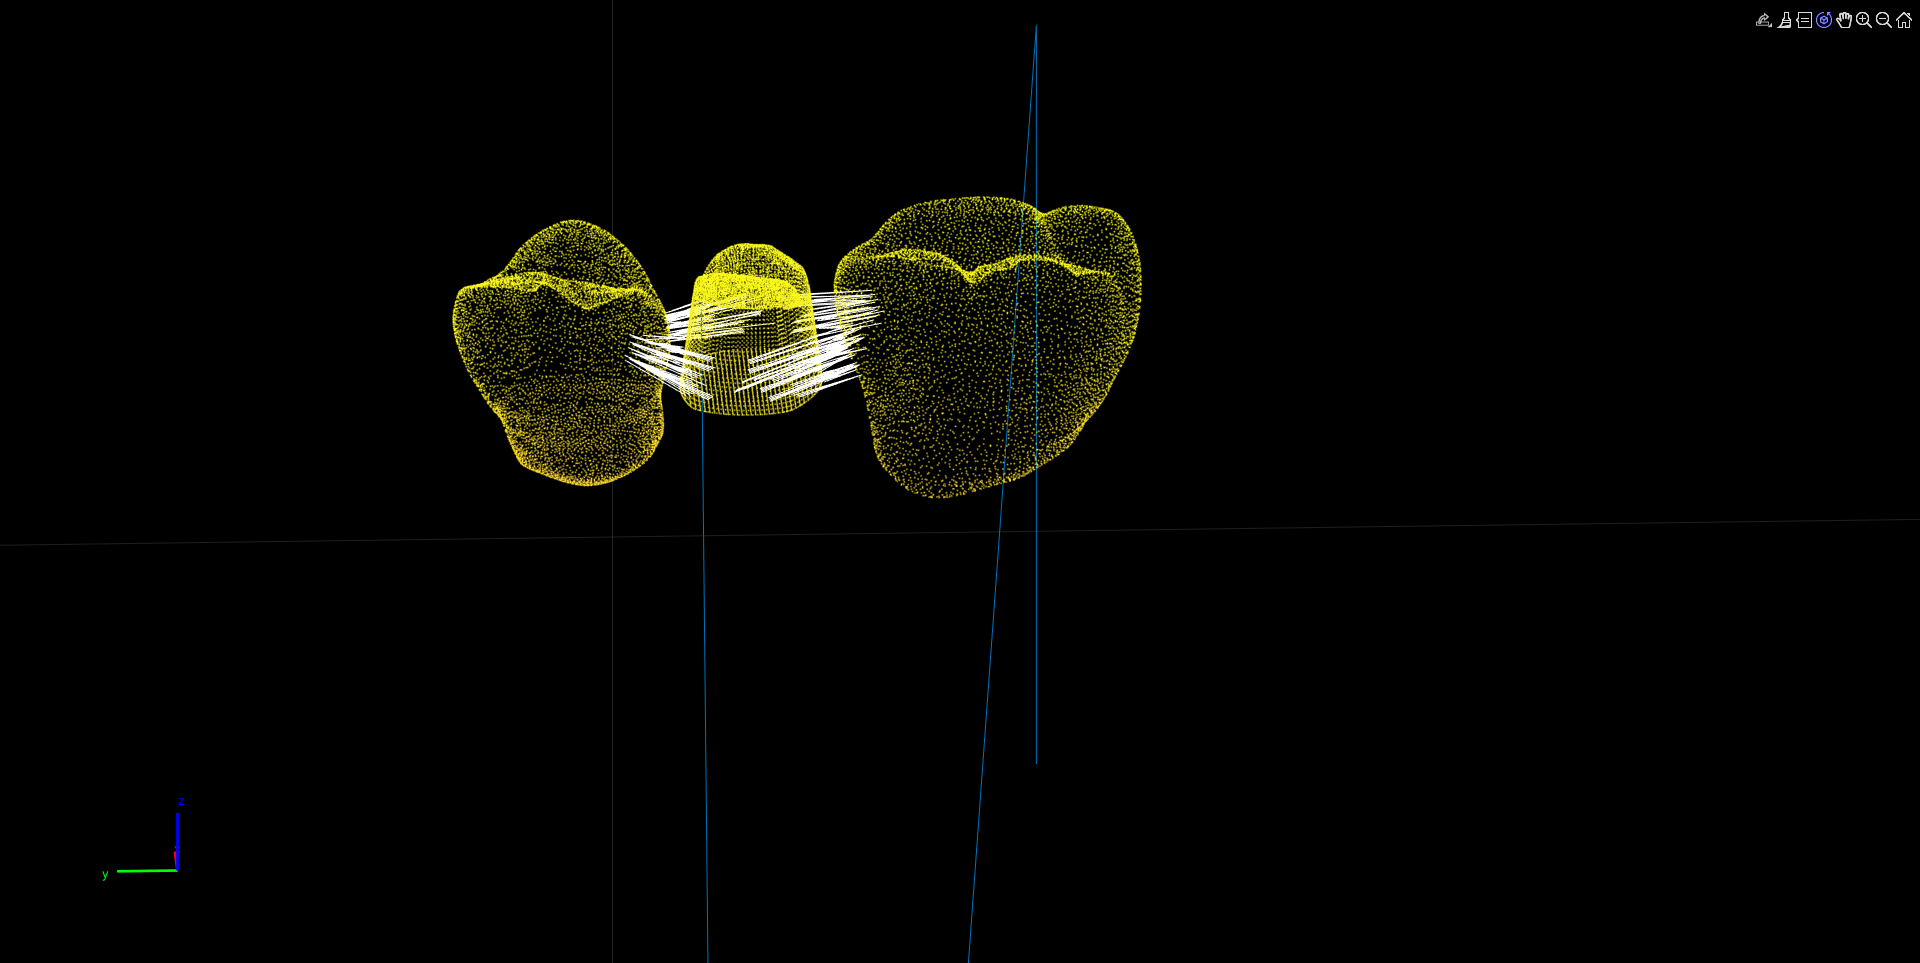

[minimum,ind,ee_arr] = min2pts(dental,q_tot,neighboringTeeth);

figure
pcshow(ptCloud_fin)
hold on
show(dental,home,'PreservePlot',false);
hold on
% plotQuarter(q1_traj_arr); hold on
% plotQuarter(q2_traj_arr); hold on
% plotQuarter(q3_traj_arr); hold on
% plotQuarter(q4_traj_arr); hold on
plotClosest(dental,q_tot,ee_arr,ind,neighboringTeeth);

% plotClosest(dental,q2_config,ee_arr,ind,ptCloud_fin);
% plotClosest(dental,q3_config,ee_arr,ind,ptCloud_fin);


## `Helper Functions`

### `getContour`

function [a,b] = getContour(ptCloud,L,H)
    k = 1;
    
    for i = 1:length(ptCloud.Location(:,3))
        j = ptCloud.Location(i,3);
        if j < H && j > L
            a(k,1) = ptCloud.Location(i,1);
            b(k,1) = ptCloud.Location(i,2);
            k = k+1;
        end
    end
end

### `getOrderedPoints`

function [P] = getOrderedPoints(a,b)
    P = [a'; b']; % coordinates / points 
    c = mean(P,2); % mean/ central point 
    d = P-c ; % vectors connecting the central point and the given points 
    th = atan2(d(2,:),d(1,:)); % angle above x axis
    [th, idx] = sort(th);   % sorting the angles 
    P = P(:,idx); % sorting the given points
    P = [P P(:,1)]; % add the first at the end to close the polygon 
end

### `smoothCurve`

function [smoothX, smoothY] = smoothCurve(P,windowWidth,polynomialOrder)
    smoothX = sgolayfilt(P(1,:), polynomialOrder, windowWidth);
    smoothY = sgolayfilt(P(2,:), polynomialOrder, windowWidth);
end

### `getQuarters`

function [q1,q2,q3,q4] = getQuarters(curve1,flag)    
    a = floor(length(curve1)/4);
%     curve1 = circshift(curve1,floor(a/2));
    curve1 = [curve1; curve1(1,:)];
    q1 = [curve1((1:a),1),curve1((1:a),2),curve1((1:a),3)];
    q2 = [curve1((a:2*a),1),curve1((a:2*a),2),curve1((a:2*a),3)];
    q3 = [curve1((2*a:3*a),1),curve1((2*a:3*a),2),curve1((2*a:3*a),3)];
    q4 = [curve1((3*a:end),1),curve1((3*a:end),2),curve1((3*a:end),3)];
    
    if(flag==1)
        plot3(q1(:,1),q1(:,2),q1(:,3),"LineWidth",1);hold on;
        plot3(q2(:,1),q2(:,2),q2(:,3),"LineWidth",1);hold on;
        plot3(q3(:,1),q3(:,2),q3(:,3),"LineWidth",1);hold on;
        plot3(q4(:,1),q4(:,2),q4(:,3),"LineWidth",1);hold on;
    end
end

function [ax, figHandle] = exampleHelperVisualizeCollisionEnvironment(collisionObjectArray)
%exampleHelperVisualizeCollisionEnvironment Visualize a set of collision objects
%   given a cell array of collision objects, create a figure that plots
%   these and with hold on. Return the handle to the figure's axis.
figHandle = figure;

% Show the first object
show(collisionObjectArray{1});

% Get axis properties and set hold
ax = gca;
hold all;

% Show remaining objects
for i = 2:numel(collisionObjectArray)
    show(collisionObjectArray{i}, "Parent", ax);
end

% Set axis properties
axis equal;

end

### `Closest Point Function:`

function [minimum,ind,ee_arr] = min2pts(bot,traj,ptCloud)
    hyp = zeros(length(ptCloud.Location(:,1)),length(traj(1,:)));
    ee_arr = zeros(length(traj(1,:)),3);
    
    for i = 1:1:length(traj(1,:))
        transform = getTransform(bot,traj(:,i),'Body6','base');
        ee = transform(1:3,4);
        ee_arr(i,:) = transpose(ee);
        d = abs(bsxfun(@minus, ee_arr(i,:), ptCloud.Location));
        hyp(:,i) = sqrt(d(:,1).^2 + d(:,2).^2 + d(:,3).^2); %Store hyp of each point at each frame
    end
    
    [minimum,ind] = min(hyp);
end

### `Plot Distance between ee and closest point function:`

function [] = plotClosest(bot,traj,ee_arr,ind,ptCloud)
    fps = 20;
    r = rateControl(fps);
    set(gcf,'Visible','on')
    pcshow(ptCloud)
    hold on
    axis(1000*[-0.4 0.5 -0.3 0.3 -0.2 0.2])
    for i = 1:1:length(traj(1,:))
        show(bot,traj(:,i),'PreservePlot',false);
%         show(bot,traj(:,i),'PreservePlot',false);
        drawnow
        waitfor(r);
        hold on
        line([ee_arr(i,1) ptCloud.Location(ind(i),1)],[ee_arr(i,2) ptCloud.Location(ind(i),2)],[ee_arr(i,3) ptCloud.Location(ind(i),3)],'Color','w')
%         plot3(ee_arr(i,1),ee_arr(i,2),ee_arr(i,3),'Marker','.');
    end
end

### `Order Trajectory based on quarters:`

function [q_traj_arr] = orderQuarter(q_arr)
    %Construct q1 trajectory
    %Start from upper and outer contour
    len_q_z = length(q_arr(:,1)) - 2; %Exclude upper two bc top of tooth
    len_q_c = length(q_arr(1,:)); %Number of contours
    
    
    for j = 0:len_q_c-1 %Different contours
        for i = 0:len_q_z-1 %Different z levels
            q_traj = q_arr{len_q_z-i,len_q_c-j};
            if j == 0 && i == 0 %Need to initialize q1_traj_arr
                q_traj_arr = q_traj;
            else
                if mod(i,2) ~=0  %Reverse every other path
                    q_traj = flipud(q_traj);
                end
                q_traj_arr = vertcat(q_traj_arr,q_traj); %Append to bottom of array
            end
        end
    end
end

### `Plot Quarter Trajectory:`

function [] = plotQuarter(q_traj_arr)
    labels = cellstr( num2str([1:length(q_traj_arr(:,1))]') );
    
    plot3(q_traj_arr(:,1),q_traj_arr(:,2),q_traj_arr(:,3),"LineWidth",1);
    text(q_traj_arr(:,1),q_traj_arr(:,2),q_traj_arr(:,3), labels, 'VerticalAlignment','bottom', ...
                                 'HorizontalAlignment','right')
end

### `Finding Home Config`

function homeConfig = findHomeConfig(ptCloud_fin)
    x_max = max(ptCloud_fin.Location(:,1));
    x_min = min(ptCloud_fin.Location(:,1));
    y_max = max(ptCloud_fin.Location(:,2));
    y_min = min(ptCloud_fin.Location(:,2));
    x = (x_max + x_min)/2;
    y = (y_max + y_min)/2;
    z = -0.04;
    homeConfig = [x y z];
end

### `Check if path in collision or not`

function isTrajectoryInCollision = isInCollision(q, collisionMesh, robot)
    worldCollisionArray = {collisionMesh};
%     ik = inverseKinematics("RigidBodyTree",robot);
%     weights = ones(1,6);
%     
    rng(0); % start with a fixed seed to get repeatable results.
%     startConfig = ik("Body5",startPose,weights,robot.homeConfiguration);
%     endConfig = ik("Body5",endPose,weights,robot.homeConfiguration);
%     
%     
%     t = 200;
%     q = trapveltraj([homeConfiguration(robot),startConfig,endConfig],t,"EndTime",2);
    
    % Initialize outputs
    inCollision = false(length(q), 1); % Check whether each pose is in collision
    worldCollisionPairIdx = cell(length(q),1); % Provide the bodies that are in collision
    
    for i = 1:length(q)
        
        [inCollision(i),sepDist] = checkCollision(robot,q(:,i),worldCollisionArray,"IgnoreSelfCollision","on","Exhaustive","on");
        
        [bodyIdx,worldCollisionObjIdx] = find(isnan(sepDist)); % Find collision pairs
        worldCollidingPairs = [bodyIdx,worldCollisionObjIdx]; 
        worldCollisionPairIdx{i} = worldCollidingPairs;
        
    end
    
    %see if there is any collision
    isTrajectoryInCollision = any(inCollision);
end